# **Planificación de trayectorias en el espacio articular (JOINT-SPACE) **

En este ejemplo, ya se dispone del camino (un conjunto de puntos intermedios) de nuestro planificador de tareas, y queremos generar una trayectoria para que un manipulador siga estos waypoints a lo largo del tiempo. 

Cargar robot

clc;
clear;
close all;
IRB120=loadrobot("abbIrb120",'Gravity',[0 0 -9.81], 'DataFormat',"column");
endEffector = 'tool0';
qHome = homeConfiguration (IRB120);
numJoints = length (qHome);

# Generación de trayectorias: puntos en el espacio

## Especificaciones del camino (puntos en el espacio)

Definición de la posición home y definición de cinco puntos (posicion y orientación) de paso de la trayecotria

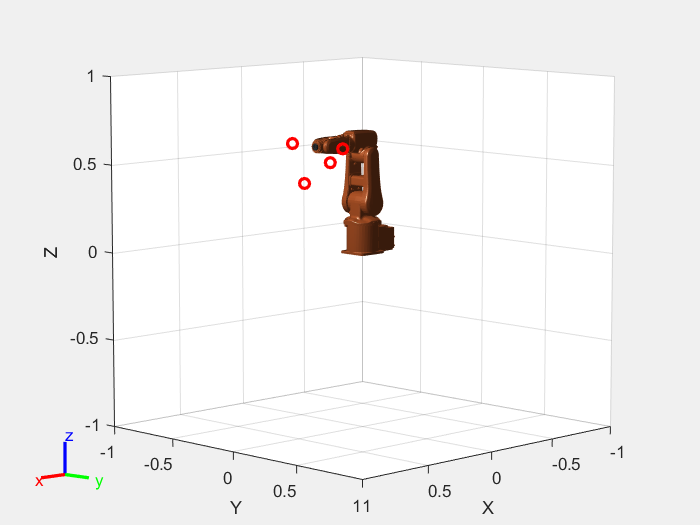

%posiciones
toolPositionHome = [0.455    0.001    0.434];  %[x, y. z]
waypoints = toolPositionHome' + ... 
            [0 0 0 ; -0.1 0.2 0.2 ; -0.2 0 0.1 ; -0.1 -0.2 0.2 ; 0 0 0]';
%orientaciones mediante angulos de euler
orientations = [pi/2    0   pi/2;
               (pi/2)+(pi/4)      0   pi/2; 
                pi/2    0   pi;
               (pi/2)-(pi/4)       0    pi/2;
                pi/2    0   pi/2]';

figure
set(gcf,'Visible','on')
show(IRB120,qHome,'Frames','off','PreservePlot',false);
hold all
plot3(waypoints(1,:),waypoints(2,:),waypoints(3,:),'ro','LineWidth',2);

## Cálculo de la cinemática inversa

Calculamos la configuración del robot en los puntos de paso especificados mediante la cinemática inversa. 

ik = inverseKinematics('RigidBodyTree',IRB120);
weights = [1 1 1 1 1 1]';
ikInitGuess = qHome;
numWaypoints = size(waypoints,2);
jointWaypoints = zeros(numJoints,numWaypoints);

for i = 1:numWaypoints
    pose = trvec2tform(waypoints(:,i)') * eul2tform (orientations (:,i)');
    qSol = ik(endEffector,pose,weights,ikInitGuess);
    jointWaypoints(:,i) = qSol';
    ikInitGuess = qSol;
end

## Más especificaciones de la trayectoria

Definimos los tiempos de la trayecotria y las velocidades y aceleracones

waypointTimes = 0:7:28;
ts = 0.25;
trajTimes = 0:ts:waypointTimes(end);

waypointVels = 0.1 *[ 0  1  0;
                     -1  0  0;
                      0 -1  0;
                      1  0  0;
                      0	 1  0]';

waypointAccels = zeros(size(waypointVels));
waypointAccelTimes = diff(waypointTimes)/4;

## **Generación de trayecotrias utilizando interpolación**

Generación de la trayectoria utilizando interpolación cúbica, de quinto orden, de velocidad trapezoidal o por B-Splines.

- Trayectoria trapezoidal

- Trayectoria cúbica: polinomio de 3º orden (4 coeficientes). Puedes definir posición y velocidad inicial y final.

- Trayectoria de 5 orden (6 coeficientes ): Puedes definir posición, vellocidad y aceleración inicial y final.

trajType = "cubic";

switch trajType
    case 'trap'
        [q,qd,qdd] = trapveltraj(jointWaypoints,numel(trajTimes), ...
            'AccelTime',repmat(waypointAccelTimes,[numJoints 1]), ... 
            'EndTime',repmat(diff(waypointTimes),[numJoints 1]));
                            
    case 'cubic'
        [q,qd,qdd] = cubicpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'quintic'
         [q,qd,qdd] = quinticpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints), ...
            'AccelerationBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'bspline'
        [q,qd,qdd] = bsplinepolytraj(jointWaypoints,waypointTimes([1 end]),trajTimes);
end


## VIsualización del comportamiento de las articulaciones

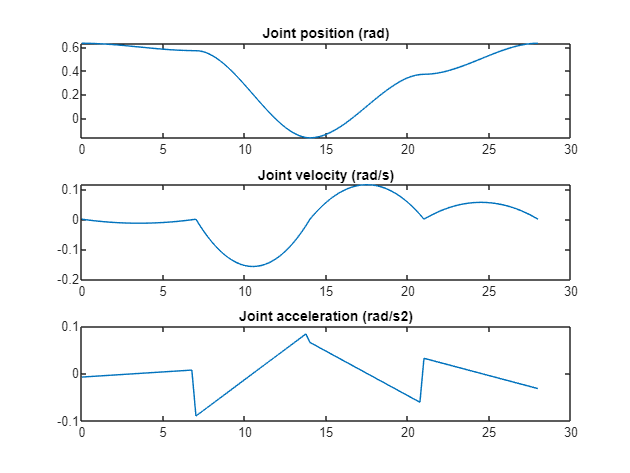

joint=2;
plotJointKinematics(joint, trajTimes, q, qd, qdd)

## Visualización de la trayecotria del robot en el espacio

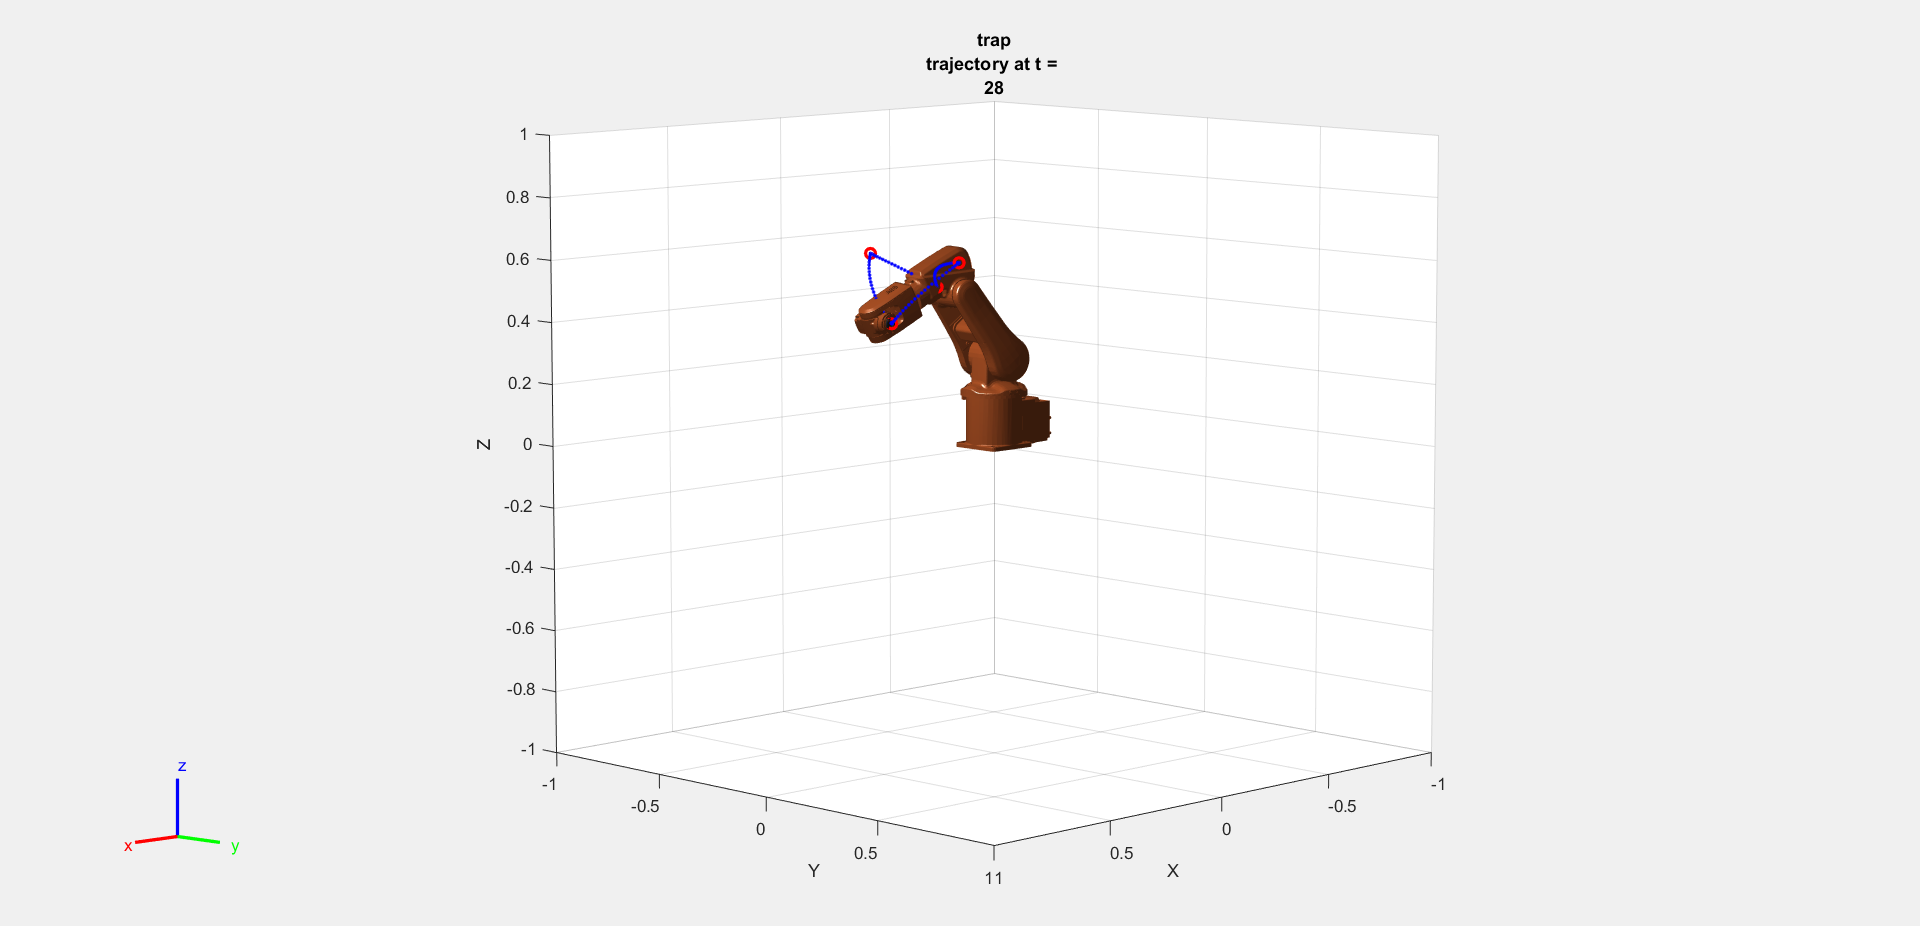

figure
set(gcf,'Visible','on')
show(IRB120,qHome,'Frames','off','PreservePlot',false);
hold all
plot3(waypoints(1,:),waypoints(2,:),waypoints(3,:),'ro','LineWidth',2);

for i = 1:numel(trajTimes)   
    config = q(:,i)'; 
    Tform = getTransform(IRB120,config',endEffector);
    pos = tform2trvec(Tform);
    plot3(pos(:,1),pos(:,2),pos(:,3),'b.-');
    % Show the robot
    show(IRB120,config','Frames','off','PreservePlot',false);
    title([trajType 'trajectory at t = ' num2str(trajTimes(i))])
    drawnow   
end